# Fórmulas de derivación numérica

El objetivo de este proyecto es observar los errores que presentan diferentes [fórmulas de derivación numérica](https://github.com/padillandrea/ANPC/blob/main/docs/FiniteDifferenceFormulas.pdf). Deben explorarse aproximaciones centradas, hacia adelante y hacia atrás; de la primera y segunda derivada; `O(h)` y `O(h^2``)`. ¿Qué fórmulas presentan menos errores? ¿Cómo dependen de `h`? ¿El error siempre disminuye si `h` se hace más pequeño? ¿Qué otro factor influye en el error? Deben tener como parámetros de entrada la función `f` a derivar y el punto `x`. Para obtener el valor exacto de la derivada, deben calcularla simbólicamente. Ver la sección *Total numerical error* del libro de texto.

f = @(x) -0.1 * x.^4 - 0.15 * x.^3 - 0.5 * x.^2 - 0.25 * x + 1.2;
x = 0.5;
h = 1;
n = 11;
[hs, error] = firstDerForwardOrder1(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    1.325000000000000   0.091099999999999   0.008785099999991   0.000875350099943   0.000087503499873   0.000008750028351   0.000000874972188   0.000000086602818   0.000000008887207   0.000000035521714   0.000000075500588


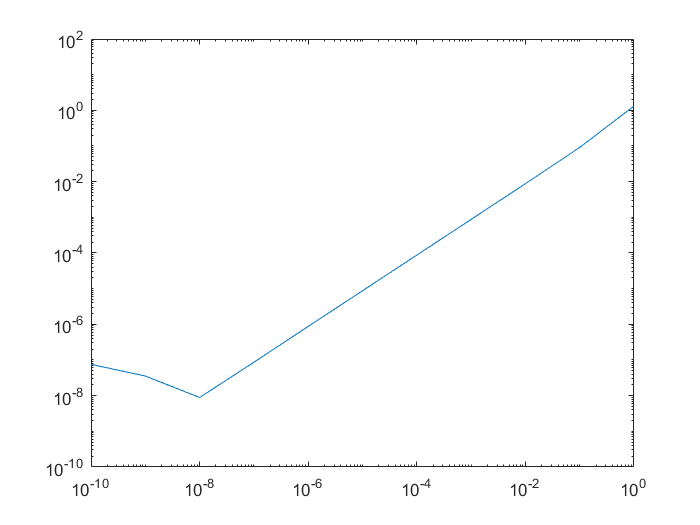

format short
loglog(hs(1:11),error)

[hs, error] = firstDerForwardOrder2(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    1.300000000000000   0.007600000000002   0.000070600000013   0.000000700600040   0.000000007000085   0.000000000077844   0.000000000005423   0.000000001104800   0.000000008887207   0.000000035521714   0.000000630612101


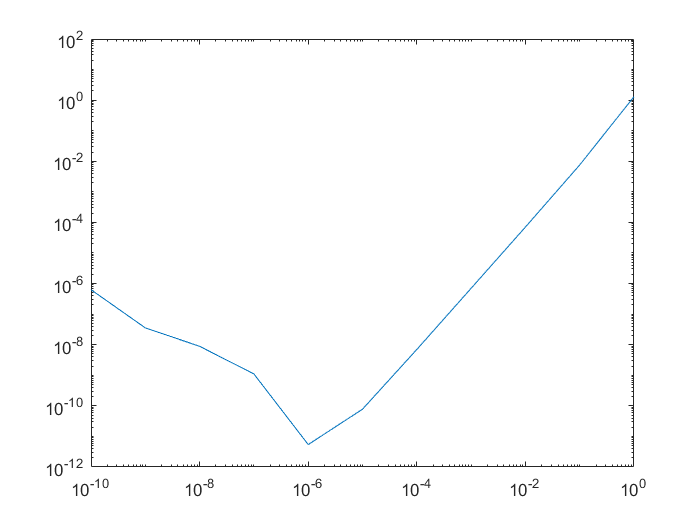

format short
loglog(hs(1:11),error)

[hs, error] = firstDerCentral(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    0.350000000000000   0.003499999999999   0.000034999999998   0.000000350000012   0.000000003499850   0.000000000033178   0.000000000005423   0.000000000549689   0.000000003336092   0.000000019989437   0.000000075500588


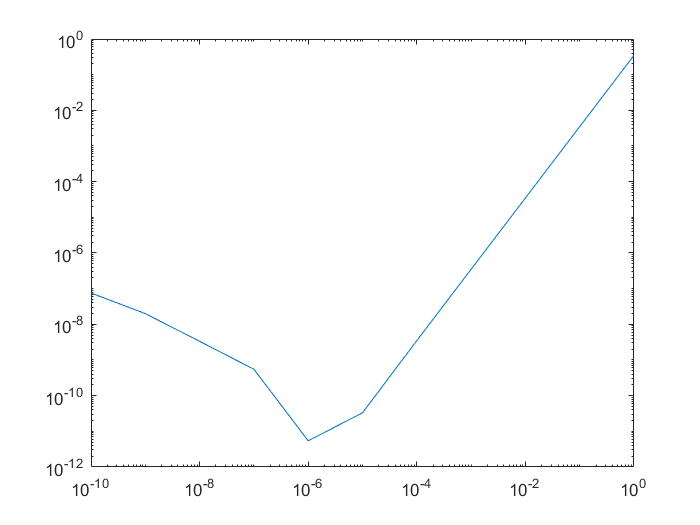

format short
loglog(hs(1:11),error)

[hs, error] = firstDerBackwardOrder1(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    0.625000000000000   0.084100000000001   0.008715099999996   0.000874650099920   0.000087496500174   0.000008749961995   0.000000874961343   0.000000087702196   0.000000002215023   0.000000075500588   0.000000075500588


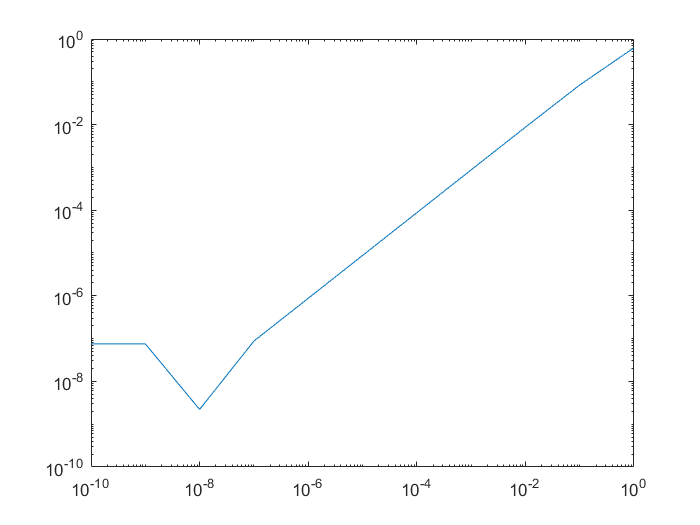

format short
loglog(hs(1:11),error)

[hs, error] = firstDerBackwardOrder2(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    0.100000000000000   0.006400000000003   0.000069399999997   0.000000699399889   0.000000007000085   0.000000000072293   0.000000000005423   0.000000001104800   0.000000008887207   0.000000075500588   0.000000479610924


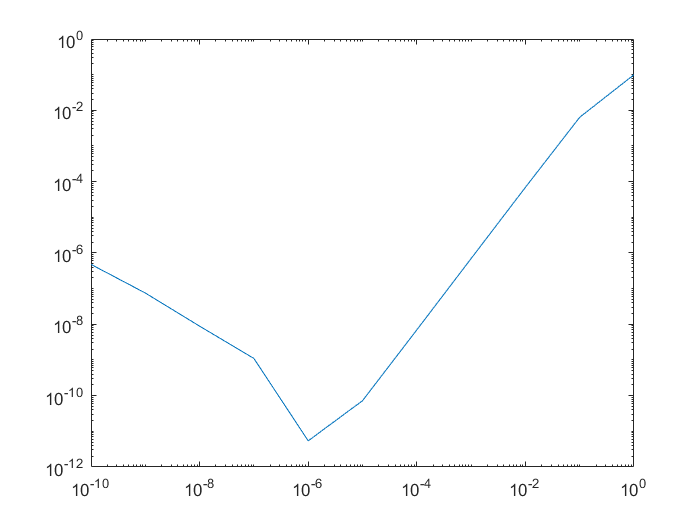

format short
loglog(hs(1:11),error)

[hs, error] = secondDerForwardOrder1(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =   18.813906250000002   0.511368009999997   0.800646638689924   0.829461734804177   0.832336867305480   0.832624312398384   0.832653056171752   0.832655927841065   0.832656229738430   0.832656047384311   0.832656250000000


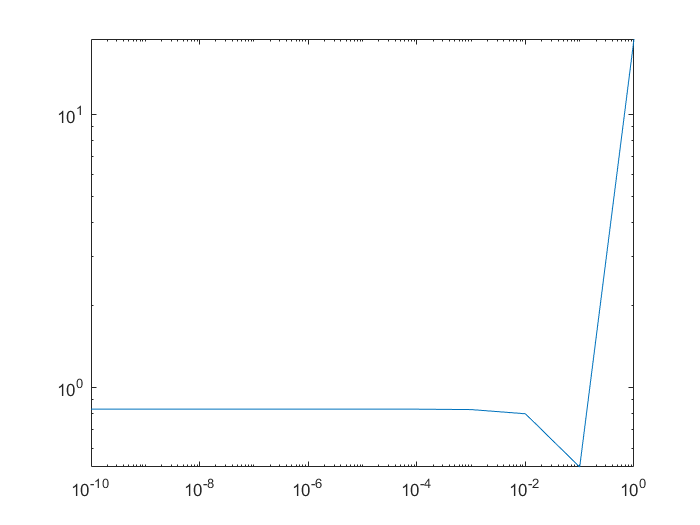

format short
loglog(hs(1:11),error)

[hs, error] = secondDerForwardOrder2(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    1.856406249999998   0.547156089999984   0.801028938004742   0.829465566506887   0.832336905618838   0.832624312722563   0.832653055563906   0.832655925814909   0.832656209476860   0.832654426459681   0.832648145391642


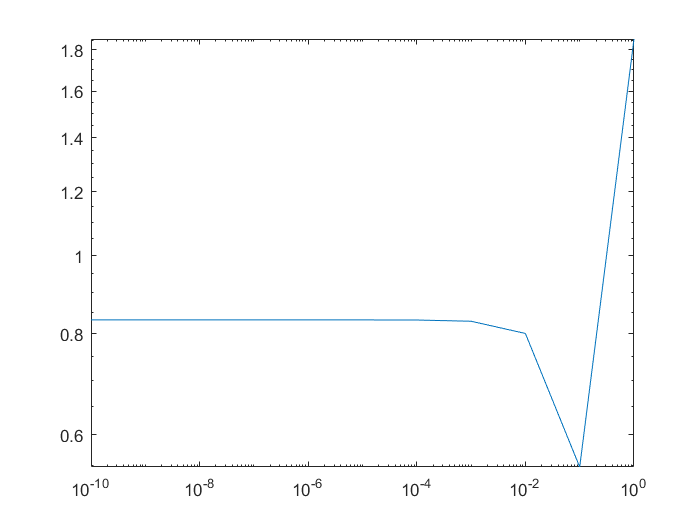

format short
loglog(hs(1:11),error)

[hs, error] = secondDerCentral(f, x, h, n)

hs =    1.000000000000000   0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000   0.000000100000000   0.000000010000000   0.000000001000000   0.000000000100000   0.000000000010000


error =    1.076406250000000   0.543611290000000   0.801024642000064   0.829465562135950   0.832336905624915   0.832624312823869   0.832653056374368   0.832655931893378   0.832656229738430   0.832656452615715   0.832656250000000


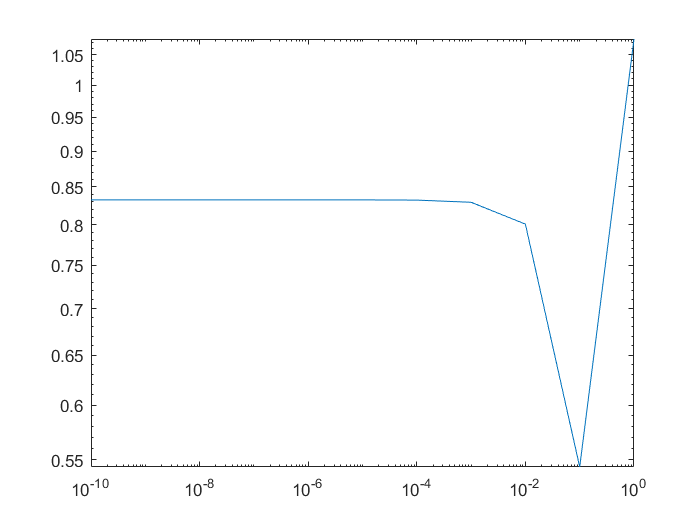

format short
loglog(hs(1:11),error)

## Funciones

function [harr, err] = firstDerForwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (f(x+harr(i)) - f(x)) / harr(i));
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = firstDerForwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (-3/2*f(x) + 2*f(x+harr(i)) - 1/2*f(x+2*harr(i))) / harr(i));
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = firstDerCentral(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (f(x + harr(i)) - f(x - harr(i))) / (2 * harr(i)));
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = firstDerBackwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (f(x) - f(x-harr(i))) / harr(i));
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = firstDerBackwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (3/2*f(x) - 2*f(x-harr(i)) + 1/2*f(x-2*harr(i))) / harr(i));
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = secondDerCentral(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (f(x - harr(i)) - 2*f(x) + f(x + harr(i))) / harr(i))^2;
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = secondDerForwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (f(x) - 2*f(x+harr(i)) + 1*f(x+2*harr(i))) / harr(i))^2;
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end


function [harr, err] = secondDerForwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    format long
    df = matlabFunction(diff(sym(f)));
    harr = NaN(1, n);
    harr(1) = h;
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(df(x) - (2*f(x) - 5*f(x+harr(i)) + 4*f(x+2*harr(i)) - f(x+3*harr(i))) / harr(i))^2;
        harr(i + 1) = harr(i) / 10;
        i = i + 1;
    end
end